Controllo se è rimasta aperta la porta seriale

if(exist('STM32_ser', 'var'))
    delete(STM32_ser);
end

baudrate = 1000000

baudrate = 1000000

porte_libere = serialportlist("available")

porte_libere = 1×2 string array
    "COM4"    "COM6"


STM32_ser = serialport(porte_libere(end), baudrate , Timeout=2);

Connetto alla seriale

buff_size = 400;
measures = 2;

Numero_Misure = 220

Numero_Misure = 220

l =  buff_size*measures

l = 800

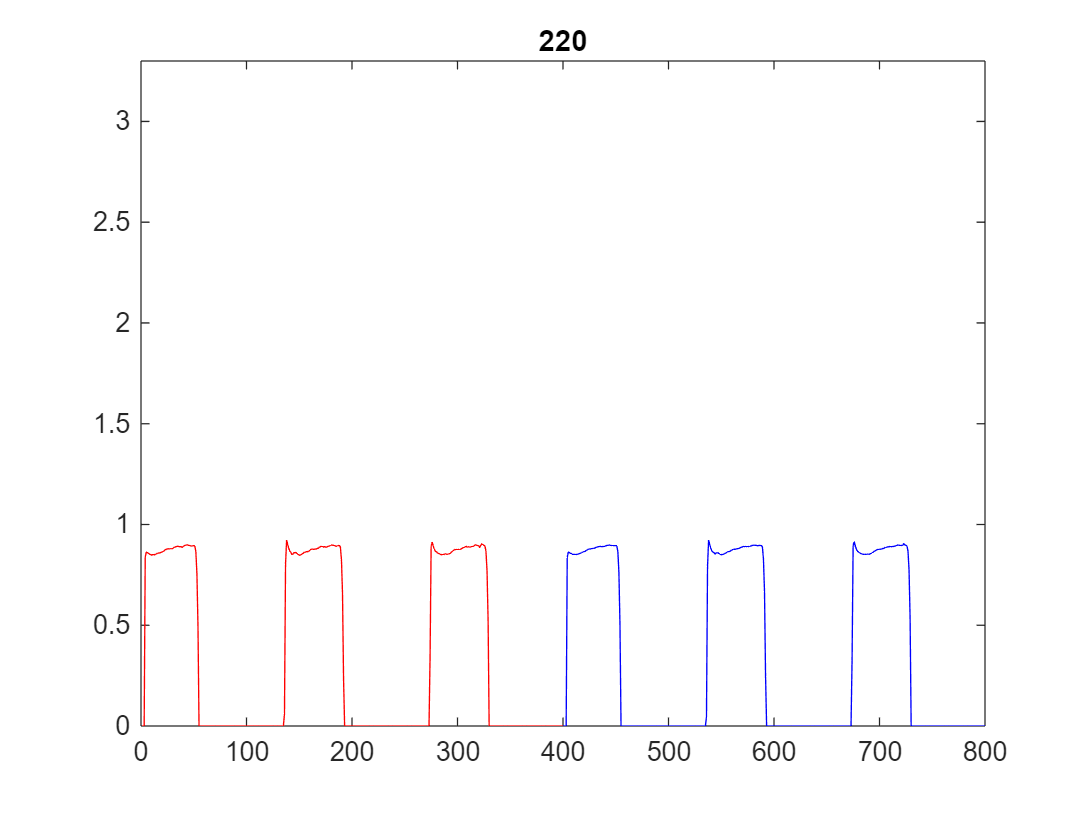

data_buffer = zeros(Numero_Misure, buff_size);
index = 1;

while (index < Numero_Misure+1)
% while 1

    STM32_ser.write('?','char');
    data = STM32_ser.read(l,'uint16') ./ 2^16 * 3.3;

    figure(1);
    plot(1:l/2, data(1:l/2), 'r', ...
        l/2:l, data(l/2:l), 'b' )
    ylim([0,3.3]);
    title(index);

    data_buffer(index, :) = data(1:buff_size);
    index = index +1;
    drawnow
end

max_val = zeros(0,Numero_Misure);
for i=1:Numero_Misure
    max_val(i) = max(data_buffer(i,:));
end
bins = int32(1 + log(length(max_val)/log(2)))

bins = int32
7

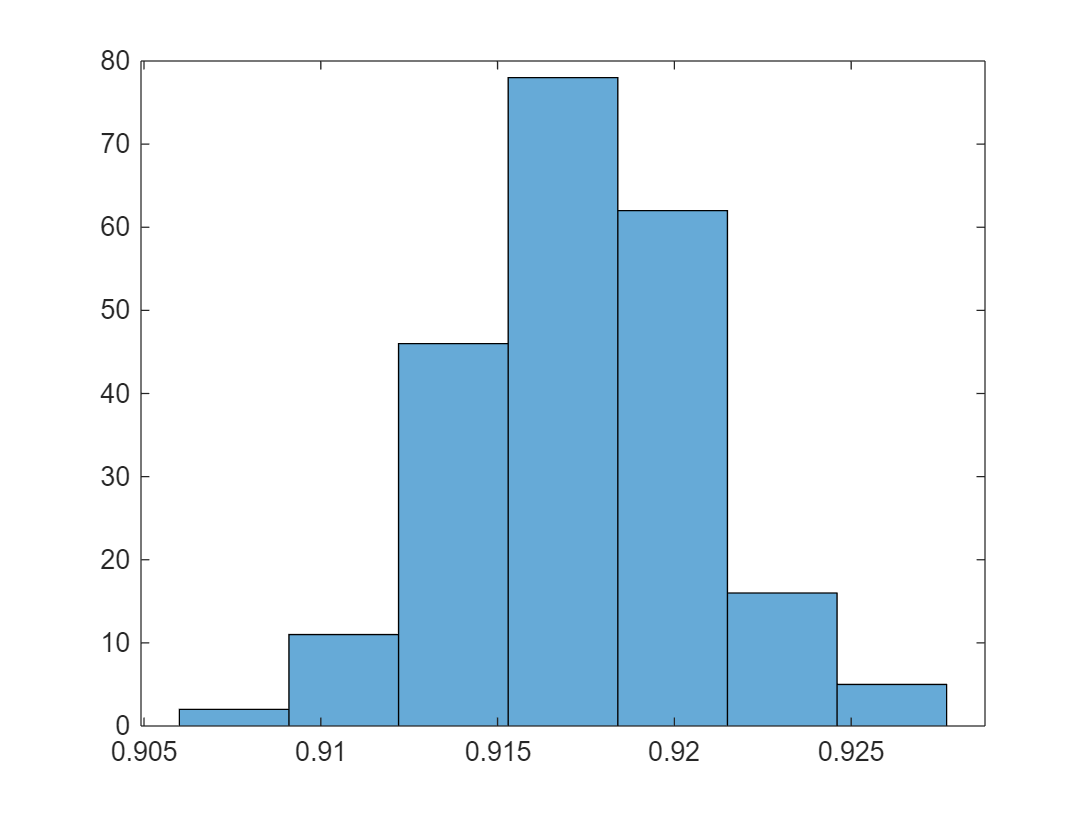

histogram(max_val,bins)